# Assignment 3

clear; close all; clc

M = importfile("TESTE_3");

time = (M(:,35)-M(1,35))/1000; %in s

Check timestap in ms

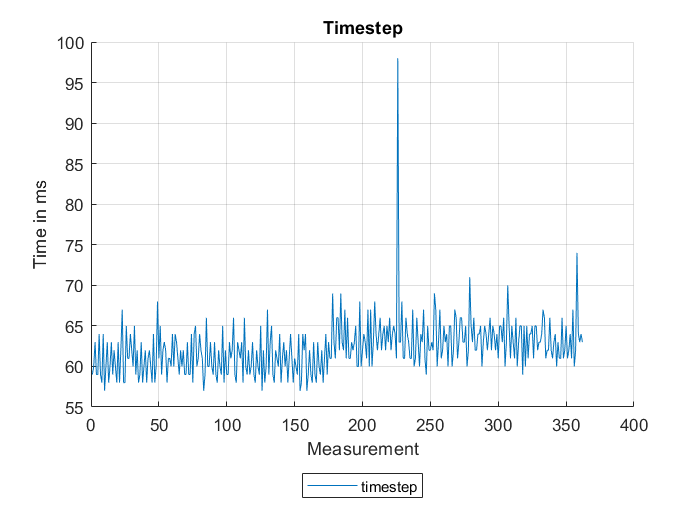

i=1;
for i=1:(height(M)-1)
    tijdstap(i)= (M(i+1,35)-M(i,35));
    i=i+1;
end


 
timestep = figure;
nexttile
grid on
hold on
plot(tijdstap)
title 'Timestep'
xlabel 'Measurement'
ylabel 'Time in ms'
legend ('timestep','Location','southoutside','Orientation','horizontal')

Check calibration

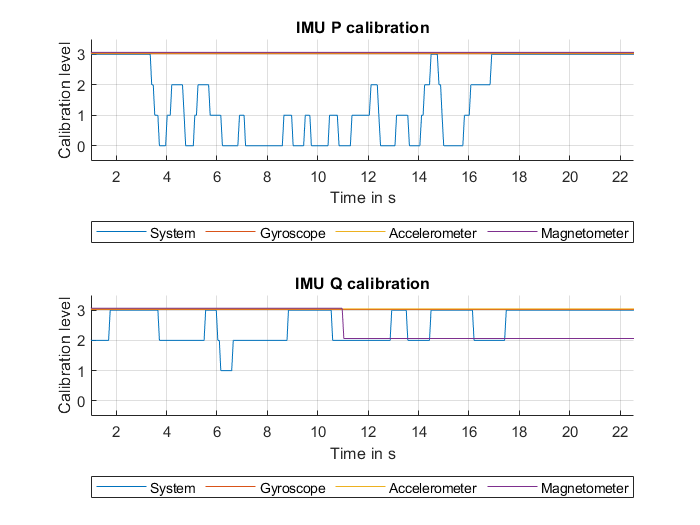

calibration = figure;
tiledlayout(2,1)
nexttile
grid on
hold on
plot (time,M(:,17)+0.00)
plot (time,M(:,18)+0.02)
plot (time,M(:,19)+0.04)
plot (time,M(:,20)+0.06)
title 'IMU P calibration'
xlabel 'Time in s'
ylabel 'Calibration level'
axis([1 time(height(time)) -0.5 3.5])
legend('System','Gyroscope','Accelerometer','Magnetometer','Location','southoutside','Orientation','horizontal')

nexttile
hold on
grid on
plot (time,M(:,2)+0.00)
plot (time,M(:,3)+0.02)
plot (time,M(:,4)+0.04)
plot (time,M(:,5)+0.06)
title 'IMU Q calibration'
xlabel 'Time in s'
ylabel 'Calibration level'
axis([1 time(height(time)) -0.5 3.5])
legend('System','Gyroscope','Accelerometer','Magnetometer','Location','southoutside','Orientation','horizontal')
hold off

filter inputs    

run filtertje.m

Elapsed time is 0.124669 seconds.


## Define parameters and matrices

Here we define the symbolic variables needed for this assignment.

syms q3 q4 q7 u3 u4 u5 u7 u3_d u4_d u7_d %lambda 
syms w_imuP_x w_imuP_y w_imuP_z w_imuQ_x w_imuQ_y w_imuQ_z
syms acc_imuP_x acc_imuP_y acc_imuP_z acc_imuQ_x acc_imuQ_y acc_imuQ_z d1x d1y d1z d1x d2y d2z
global lambda yaw_P roll_P pitch_P yaw_Q roll_Q pitch_Q no q3_berekend q4_berekend q7_berekend

lambda = deg2rad(23);



% contact rear wheel to imuP
px = 0.06 ;
py = 0.35 ;
pz = -0.86;

% contact rear wheel to pivit axis point
hx = 0.83 ; 
hy = 0.0 ;
hz = -0.85;

% pivit axis point to imuQ
qx = -0.08 ; 
qy = 0.16 ;
qz = -0.23 ;

The first row of variables is defined as illustrated below. All the q-values are angles, all the u-values are angular velocities (derivatives of the q-values) and all the u_d-values are angular accelerations (derivatives of the u-values).

The second row of variables are the angular velocities measured by the IMU at point P and Q and the third row are the linear accelerations measured by the IMU and the constant distances between the axis of rotation and the IMU.

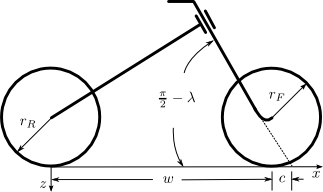

    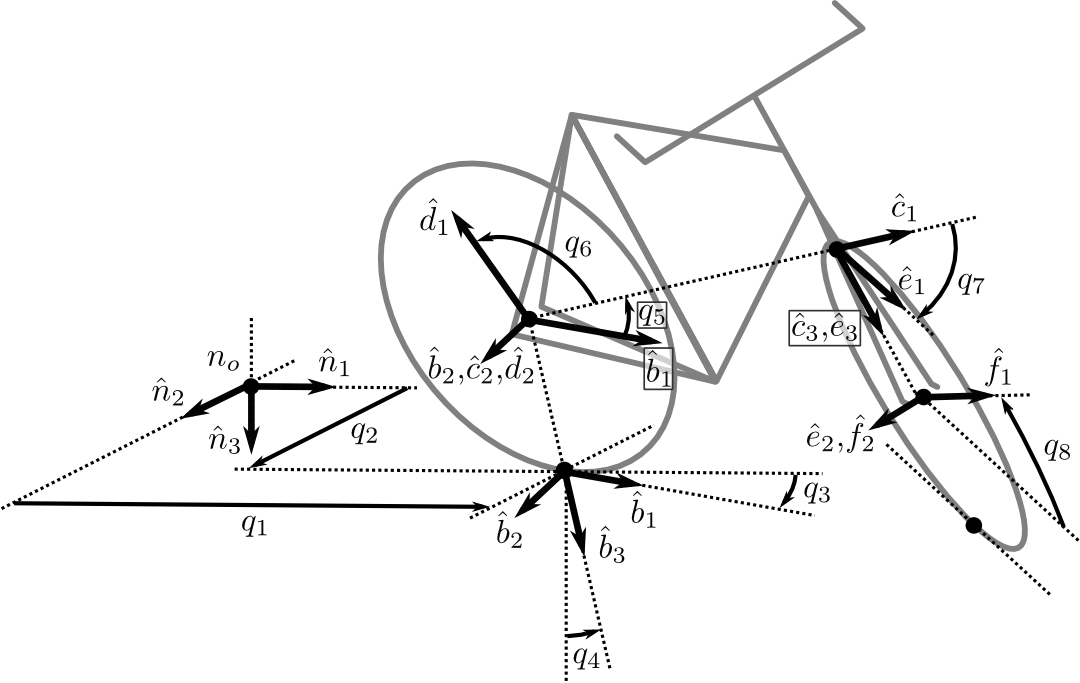

Rotation matrices defined as in the picture below:

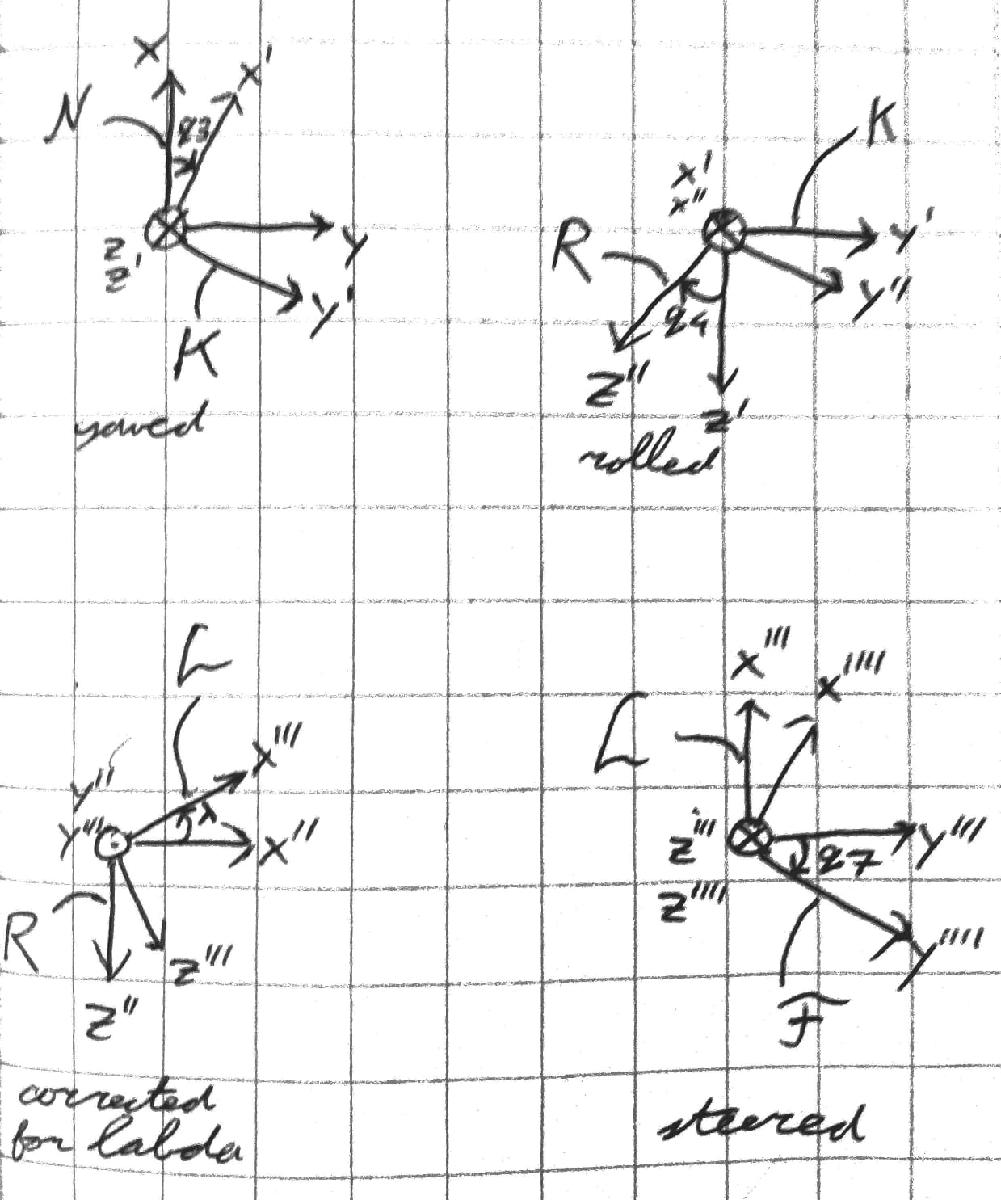

This is translated to the following code:

NCK = [cos(q3) -sin(q3) 0 ; sin(q3) cos(q3) 0 ; 0 0 1];
KCR = [1 0 0 ; 0 cos(q4) -sin(q4) ; 0 sin(q4) cos(q4)];
RCL = [cos(lambda) 0 sin(lambda);0 1 0 ;-sin(lambda) 0 cos(lambda)];
LCF = [cos(q7) -sin(q7) 0 ; sin(q7) cos(q7) 0 ; 0 0 1];
NCR = NCK*KCR;
RCN = transpose(NCR);
RCF = RCL*LCF;
FCR = transpose(RCF);
NCF = NCR*RCF;
LCR = transpose(RCL);
NCL = NCR*RCL;
RCK = transpose(KCR);
FCN = transpose(NCF);
FCK = transpose(KCR*RCL*LCF);

Define unit vectors

Nn1 = [1;0;0];
Nn2 = [0;1;0];
Nn3 = [0;0;1];

Kk1 = [1;0;0];
Kk2 = [0;1;0];
Kk3 = [0;0;1];

Rr1 = [1;0;0];
Rr2 = [0;1;0];
Rr3 = [0;0;1];

Ll1 = [1;0;0];
Ll2 = [0;1;0];
Ll3 = [0;0;1];

Ff1 = [1;0;0];
Ff2 = [0;1;0];
Ff3 = [0;0;1];

Express unit vectors in F-triad

Nk1 = NCK*Kk1;
Nk2 = NCK*Kk2;
Nk3 = NCK*Kk3;

Nr1 = NCR*Rr1;
Nr2 = NCR*Rr2;
Nr3 = NCR*Rr3;

Nf1 = NCF*Ff1;
Nf2 = NCF*Ff2;
Nf3 = NCF*Ff3;

Nl1 = NCL*Ll1;
Nl2 = NCL*Ll2;
Nl3 = NCL*Ll3;

Fr1= FCR*Rr1;
Fr2= FCR*Rr2;
Fr3= FCR*Rr3;

Fn1= FCN*Nn1;
Fn2= FCN*Nn2;
Fn3= FCN*Nn3;

Rn1 = RCN*Nn1;
Rn2 = RCN*Nn2;
Rn3 = RCN*Nn3;

Rf1 = RCF*Ff1;
Rf2 = RCF*Ff2;
Rf3 = RCF*Ff3;

Rk1 = RCK*Kk1;
Rk2 = RCK*Kk2;
Rk3 = RCK*Kk3;

Fk1 = FCK*Kk1;
Fk2 = FCK*Kk2;
Fk3 = FCK*Kk3;

## Calculate roll and steer angles

Input the quaternions from the IMU's and convert them to ZXY Euler angles using quat2angle (aerospace toolbox)


quat_P = [M(:,21) M(:,22) M(:,23) M(:,24)]; %[w x y z]
quat_Q = [M(:,6) M(:,7) M(:,8) M(:,9)]; %[w x y z]


[yaw_P, roll_P, pitch_P] = quat2angle(quat_P, 'ZXY');
[yaw_Q, roll_Q, pitch_Q] = quat2angle(quat_Q, 'ZXY');


correct for left-handed orientation from IMU's

yaw_P = -yaw_P;
pitch_P = -pitch_P;
yaw_Q = -yaw_Q;
pitch_Q = -pitch_Q;

correct for small offset of the 2 IMUs

yaw_P = yaw_P-deg2rad(4);
roll_P = roll_P-deg2rad(4.75);
pitch_P = pitch_P+deg2rad(0.9);

yaw_Q =yaw_Q+deg2rad(1);
roll_Q = roll_Q+deg2rad(5.8);
pitch_Q = pitch_Q+deg2rad(1.7);

Making sure the yaw angles are continious and without big jumps.

fix = 1;
while fix == 1
    fix = 0;
    i=1;
        for i = 1:length(yaw_P)-1
            if yaw_P(i)-yaw_P(i+1) < -pi
                yaw_P(i+1) = yaw_P(i+1) - 2*pi;
                fix = 1;
            elseif yaw_P(i)-yaw_P(i+1) > pi
                yaw_P(i+1) = yaw_P(i+1) + 2*pi;
                fix = 1;
            end
            i=i+1;
        end

    i=1;
        for i = 1:length(yaw_Q)-1
            if yaw_Q(i)-yaw_Q(i+1) < -pi
                yaw_Q(i+1) = yaw_Q(i+1) - 2*pi;
                fix = 1;
            elseif yaw_Q(i)-yaw_Q(i+1) > pi
                yaw_Q(i+1) = yaw_Q(i+1) + 2*pi;
                fix = 1;
            end
            i=i+1;
        end
end

plot euler angles 

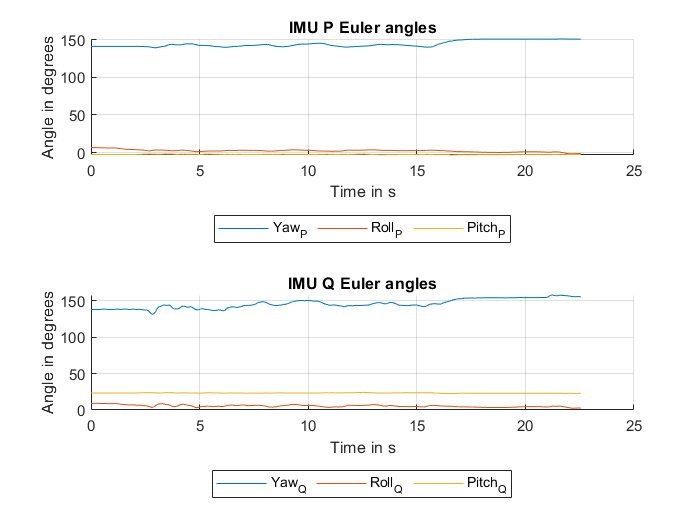

euler = figure;
tiledlayout(2,1)
nexttile
grid
hold on
plot (time,rad2deg(yaw_P))
plot (time,rad2deg(roll_P))
plot (time,rad2deg(pitch_P))
title 'IMU P Euler angles'
xlabel 'Time in s'
ylabel 'Angle in degrees'
legend('Yaw_P','Roll_P','Pitch_P','Location','southoutside','Orientation','horizontal')
hold off

nexttile
grid on
hold on
plot (time,rad2deg(yaw_Q))
plot (time,rad2deg(roll_Q))
plot (time,rad2deg(pitch_Q))
title 'IMU Q Euler angles'
xlabel 'Time in s'
ylabel 'Angle in degrees'
legend('Yaw_Q','Roll_Q','Pitch_Q','Location','southoutside','Orientation','horizontal')
hold off

**Define equations relating the yaw, roll and pitch to q3, q4 and q7**

IMU_p:    yaw_P*Rr3 + roll_P*Rr1 + pitch_P*Rr2 == (q3*Rr3 + q4*Rr1)

IMU_q:    yaw_Q*Rr3 + roll_Q*Rr1 + pitch_Q*Rr2 == (q3*Rr3 + q4*Rr1 + q7*Rf3)

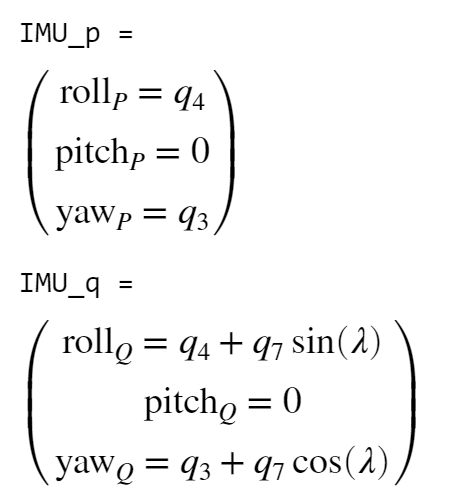

Calculate q3, q4 and from the first 3 nonlinear equations from IMU P by using the matlab function lsqnonlin, then doing the same for q7 with the equations from IMU Q and the now known q3 and q4

no = 1;
q3_berekend =  zeros(length(yaw_P),1);
q4_berekend =  zeros(length(yaw_P),1);
q7_berekend =  zeros(length(yaw_P),1);

tic
for i = 1:length(yaw_P)    
    q3_4 = lsqnonlin(@fun_angleq34_11_12,[0 0],[],[],optimset('display','off'));
    q3_berekend(no,1)= q3_4(1,1);
    q4_berekend(no,1)= q3_4(1,2);
    q__7 = lsqnonlin(@fun_angleq7_11_12, 0,[],[],optimset('display','off'));
    q7_berekend(no)= q__7;
%     lambda_q7 = lsqnonlin(@fun_angleq7_arend,[0 0],[],[],optimset('display','off'));
%     lambda_berekend(no,1)= lambda_q7(1,1);
%     q7newer_berekend(no,1)= lambda_q7(1,2);
    no=no+1;
end
toc

Elapsed time is 2.376961 seconds.


Making sure the q3 angles are continious and without big jumps.

% fix = 1;
% while fix == 1
%     fix = 0;
%     i=1;
%         for i = 1:length(yaw_P)-1
%             if q3_berekend(i)-q3_berekend(i+1) < -(pi-1);
%                 q3_berekend(i+1) = q3_berekend(i+1) - 2*pi;
%                 fix = 1;
%             elseif q3_berekend(i)-q3_berekend(i+1) > pi-1;
%                 q3_berekend(i+1) = q3_berekend(i+1) + 2*pi;
%                 fix = 1;
%             end
%             i=i+1;
%         end
%     if i == length(yaw_P)-1
%         fix = 0;
%     end
% end

Plot q3, q4, q7

q347 = figure;
nexttile
grid on
hold on
plot (time,rad2deg(q3_berekend))
plot (time,rad2deg(q4_berekend))
plot (time,rad2deg(q7_berekend))
title 'q3, q4 & q7'
xlabel 'Time in s'
ylabel 'Angle in degrees'
legend ('q3','q4','q7','Location','southoutside','Orientation','horizontal')

## Calculate the angular rates

Define state vector with desired variables

u_state = [u3;u4;u7]; 

Define state vector with IMU measured values

omega_state = deg2rad([M(:,25) M(:,26) M(:,27) M(:,10) M(:,11) M(:,12)]);

The relation of the angular velocities measured by the IMUs and the angular velocities of the bodies they're attached to is calculated as follows:

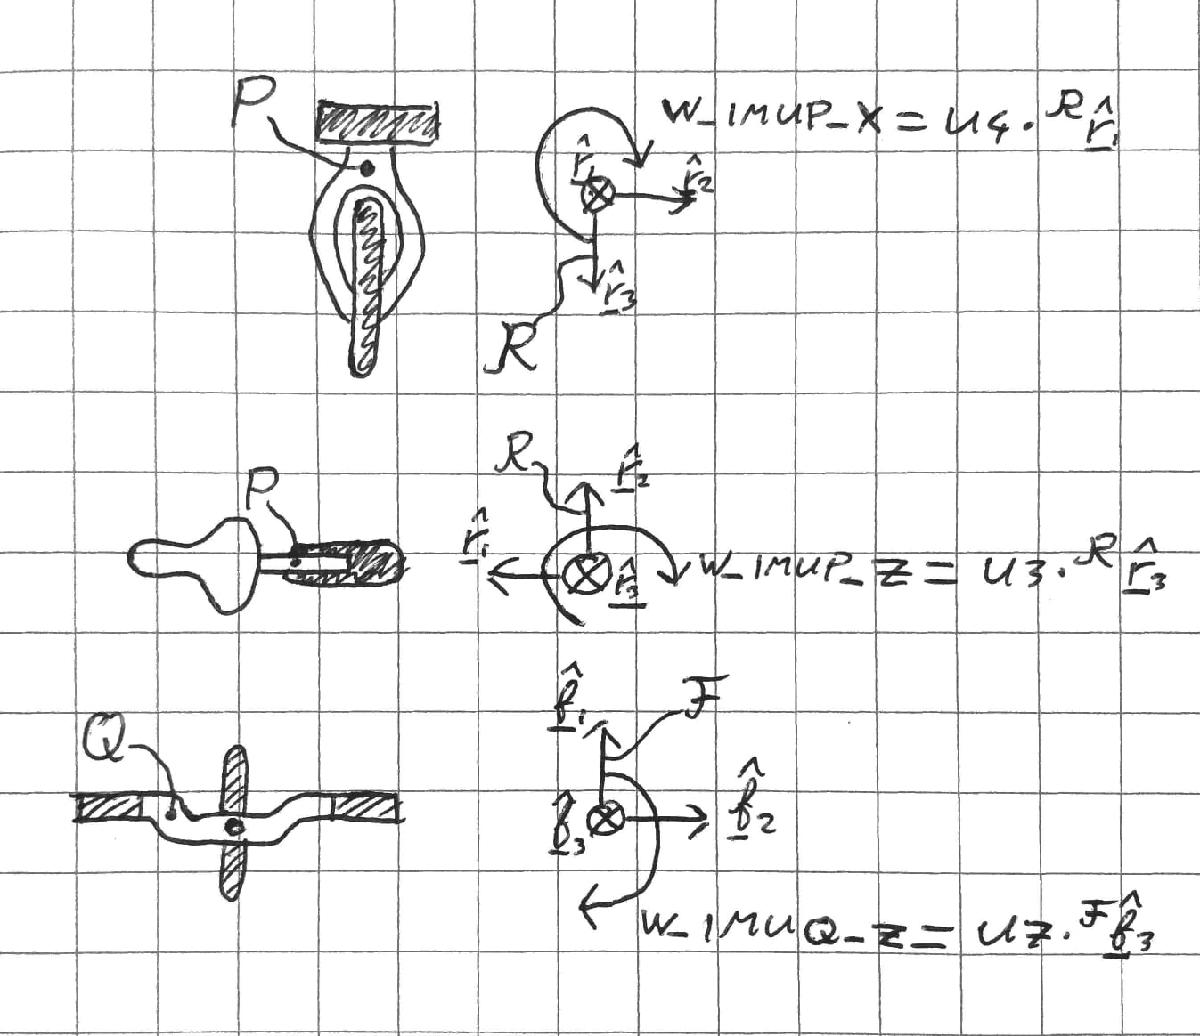

This is translated into the following code:

omega_imu_P = u3*Rk3 + u4*Rr1;
omega_imu_Q = u3*Fk3 + u4*Fr1 + u7*Ff3;
omega_imus = [omega_imu_P;omega_imu_Q];

Take the jacobian A of the IMU equations with respect to their variables in u_state.

A = jacobian(omega_imus,u_state);


$$\omega_‾ \;=\underline{\underline{A} } *\underline{u}$$
 

Where vector omega is the rotation rate of the IMUs. We want to get the u, however, since A is a non-square matrix, we have to apply the least-square method to achieve this: 


$$\underline{u} ={\left({\underline{\underline{A} } }^T *\underline{\underline{A} } \right)}^{-1} *\;{\underline{\underline{A} } }^T \;*\;\omega_‾$$


In code this translates to: 

u_state_berekend =  zeros(length(yaw_P),3);
i = 1;

tic
parfor i = 1:length(yaw_P) 
    A1 = subs(A,[q4 q7],[q4_berekend(i) q7_berekend(i)]);
    A1_t = transpose(A1);
    u_state_berekend(i,:) = (A1_t*A1)\A1_t*transpose(omega_state(i,:)); 
end
toc

Elapsed time is 150.949467 seconds.


Plotting gyro values and u3,u4&u7

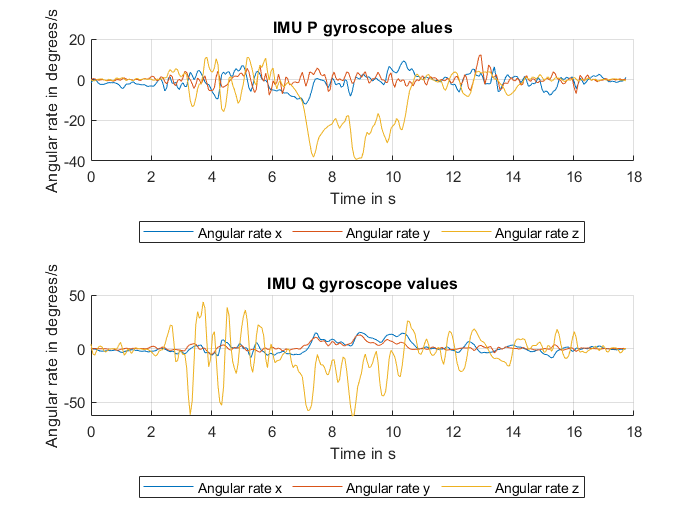

gyro = figure;
tiledlayout(2,1)
nexttile
grid
hold on
plot (time,M(:,25))
plot (time,M(:,26))
plot (time,M(:,27))
title 'IMU P gyroscope alues'
xlabel 'Time in s'
ylabel 'Angular rate in degrees/s'
legend('Angular rate x','Angular rate y','Angular rate z','Location','southoutside','Orientation','horizontal')
hold off

nexttile
grid
hold on
plot (time,M(:,10))
plot (time,M(:,11))
plot (time,M(:,12))
title 'IMU Q gyroscope values'
xlabel 'Time in s'
ylabel 'Angular rate in degrees/s'
legend('Angular rate x','Angular rate y','Angular rate z','Location','southoutside','Orientation','horizontal')
hold off

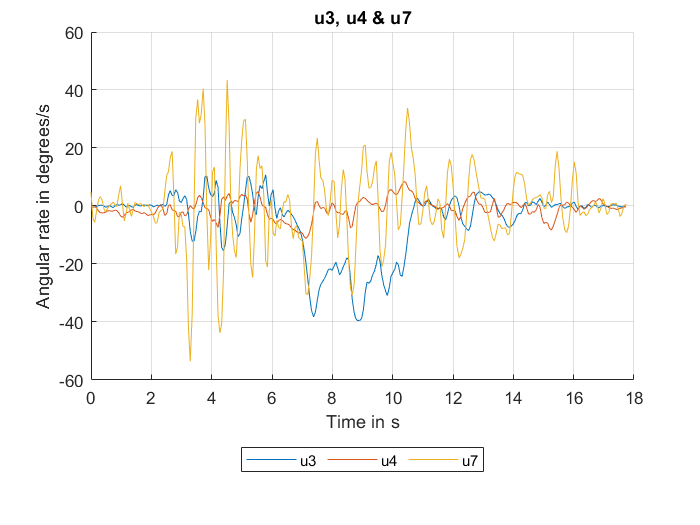


u347 = figure;
grid on
hold on
plot (time,rad2deg(u_state_berekend(:,1)))
plot (time,rad2deg(u_state_berekend(:,2)))
plot (time,rad2deg(u_state_berekend(:,3)))
title 'u3, u4 & u7'
xlabel 'Time in s'
ylabel 'Angular rate in degrees/s'
legend ('u3','u4','u7','Location','southoutside','Orientation','horizontal')
hold off

**Angular accelerations by differetiating the Angular rates**

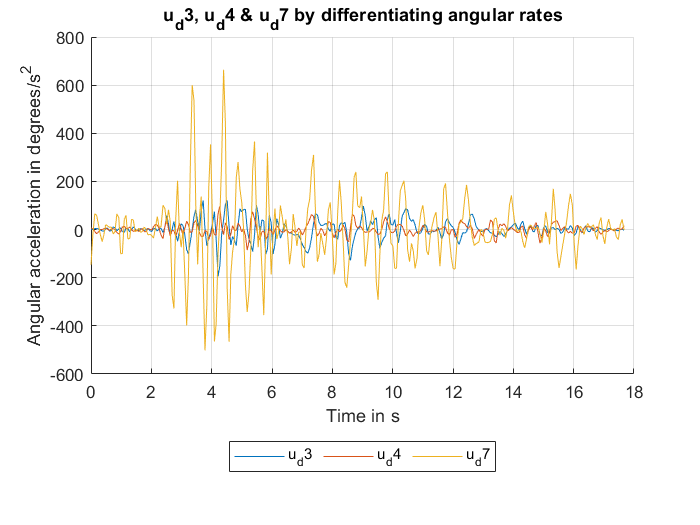

u_d3dif = zeros(length(yaw_P)-1,1);
u_d4dif = zeros(length(yaw_P)-1,1);
u_d7dif = zeros(length(yaw_P)-1,1);
i=1;
for i=1:length(yaw_P)-1
    u_d3dif(i) = ((u_state_berekend(i+1,1))-(u_state_berekend(i,1)))/(time(i+1)-time(i));
    u_d4dif(i) = ((u_state_berekend(i+1,2))-(u_state_berekend(i,2)))/(time(i+1)-time(i));
    u_d7dif(i) = ((u_state_berekend(i+1,3))-(u_state_berekend(i,3)))/(time(i+1)-time(i));
end


u_d347dif = figure;
grid on
hold on
plot (time(1:i),rad2deg(u_d3dif))
plot (time(1:i),rad2deg(u_d4dif))
plot (time(1:i),rad2deg(u_d7dif))
title 'u_d3, u_d4 & u_d7 by differentiating angular rates'
xlabel 'Time in s'
ylabel 'Angular acceleration in degrees/s^2'
legend ('u_d3','u_d4','u_d7','Location','southoutside','Orientation','horizontal')
hold off

**Angular accelerations by twice differetiating the Angles**

% u_3dif2 = zeros(length(yaw_P)-1,1);
% u_4dif2 = zeros(length(yaw_P)-1,1);
% u_7dif2 = zeros(length(yaw_P)-1,1);
% i=1;
% for i=1:length(yaw_P)-1
%     u_3dif2(i) = (q3_berekend(i+1)-q3_berekend(i))/(time(i+1)-time(i));
%     u_4dif2(i) = (q4_berekend(i+1)-q4_berekend(i))/(time(i+1)-time(i));
%     u_7dif2(i) = (q7_berekend(i+1)-q7_berekend(i))/(time(i+1)-time(i));
% end
% 
% u_d3dif2 = zeros(length(yaw_P),1);
% u_d4dif2 = zeros(length(yaw_P),1);
% u_d7dif2 = zeros(length(yaw_P),1);
% i=1;
% for i=1:length(yaw_P)-2
%     u_d3dif2(i+1) = (u_3dif2(i+1)-u_3dif2(i))/(time(i+1)-time(i));
%     u_d4dif2(i+1) = (u_4dif2(i+1)-u_4dif2(i))/(time(i+1)-time(i));
%     u_d7dif2(i+1) = (u_7dif2(i+1)-u_7dif2(i))/(time(i+1)-time(i));
% end
% 
% 
% 
% 
% u_d347dif2 = figure;
% grid on
% hold on
% plot (time,u_d3dif2)
% plot (time,u_d4dif2)
% % plot (time,u_d7dif2)
% title 'u_d3dif2, u_d4dif2 and u_d7dif2'
% xlabel 's'
% ylabel '/s^2'
% legend ('u_d3 berekend diff2','u_d4 berekend diff2','u_d7 berekend diff2','Location','southoutside','Orientation','horizontal')
% hold off

    Plot speed and acceleration in m/s and m/s^2 from magnets on rear wheel

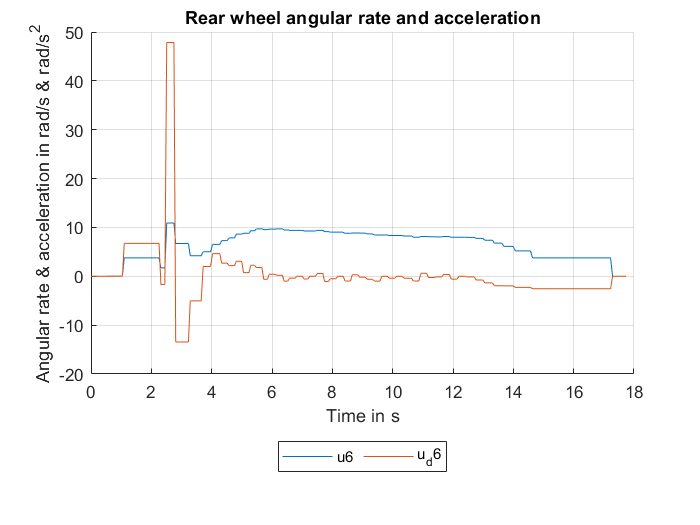

u6 = M(:,31);
u_d6 = M(:,32);

speed_and_acceleration = figure;
grid on
hold on
plot (time,u6)
plot (time,u_d6)
title 'Rear wheel angular rate and acceleration'
xlabel 'Time in s'
ylabel 'Angular rate & acceleration in rad/s & rad/s^2'
legend ('u6','u_d6','Location','southoutside','Orientation','horizontal')
hold off

## Calculate the angular accelerations

syms q3 q4 q7 u3 u4 u5 u7 u3_d u4_d u7_d %lambda 
syms w_imuP_x w_imuP_y w_imuP_z w_imuQ_x w_imuQ_y w_imuQ_z
syms acc_imuP_x acc_imuP_y acc_imuP_z acc_imuQ_x acc_imuQ_y acc_imuQ_z d1x d1y d1z d1x d2y d2z
global lambda yaw_P roll_P pitch_P yaw_Q roll_Q pitch_Q no  q3_berekend q4_berekend q7_berekend
lambda = deg2rad(23);


Define state vector with desired variables

u_dstateP = [u4_d; u3_d];
u_dstateQ = [u3_d; u4_d; u7_d];
u_d7_berekend = [u7_d];

The relation of the linear accelerations measured by the IMUs and the angular accelerations of the bodies they're attached to is calculated as follows:

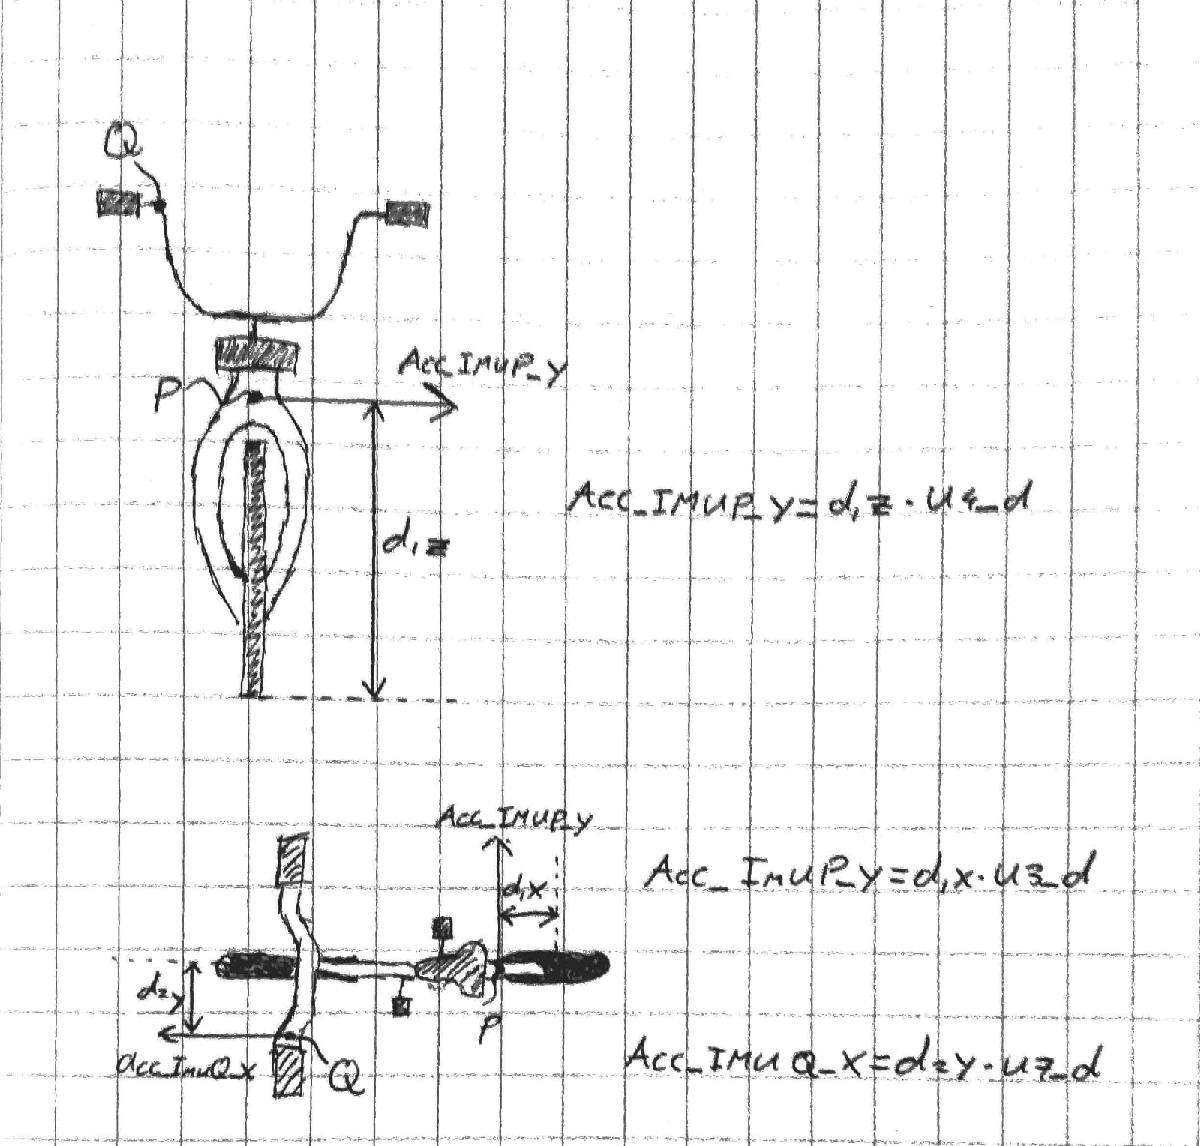

Give the position vectors for the two IMU´s

Rpo = [px; py; pz]; %Contact to IMU P 
Rho = [hx; hy; hz]; %Contact to connection H
Fqo = [qx; qy; qz]; %Connection H to IMU Q

Calculating the accelerations in C (in R-frame)

% Kc_dd = [0 u3*v 0]'; %in K-frame
% Rc_dd = RCK*Kc_dd;    %in R-frame
v = M(:,33);
% v=zeros(height(M));

% R_Omega_d_P = RCK*Rr3*u3_d+Rr1*u4_d; 
% R_Euler_AccP = -cross(Rpo,R_Omega_d_P);
% B_P = jacobian(R_Euler_AccP,u_dstateP);


u_dstate_berekend1 = zeros(length(yaw_P),2);
u7_d_dberekend = zeros(length(yaw_P),1);
i = 1;
tic
for i = 1:length(yaw_P)
    %Calculating the accelerations in C (in R-frame)
    Kc_dd = [0 u3*v(i) 0]'; %in K-frame
    Rc_dd = RCK*Kc_dd;    %in R-frame, see page 5
    
    %Taking into account the centripetal acceleration factor
    R_Omega_P = deg2rad([M(i,25); M(i,26); M(i,27)]); %rotational speed IMU P in R frame [x y z] in rad/s
    R_Cen_P = cross(R_Omega_P,cross(R_Omega_P,Rpo)); % see page 5
    
    
    R_Omega_d_P = RCK*Kk3*u3_d+Rr1*u4_d; % see page 4
    R_Euler_AccP = -cross(Rpo,R_Omega_d_P); % see page 5
    
    B_P = subs(jacobian(R_Euler_AccP,u_dstateP),q4,q4_berekend(i));
    X_dd1 = [M(i,28); M(i,29); M(i,30)]; %lineair acc IMU P in R frame [x y z] in m/s^2
    y_accP = subs(-X_dd1+Rc_dd+R_Cen_P,[q4 u3],[q4_berekend(i) (u_state_berekend(i,1))]);
    
    u_dstate_berekend1(i,:) = (transpose(B_P)*B_P)\transpose(B_P)*y_accP; % see page 6

    
    
    
    R_Cen_Q1 = cross(R_Omega_P,cross(R_Omega_P,Rho));
    R_Omega_Q = RCF*deg2rad([M(i,10); M(i,11); M(i,12)]);
    R_Cen_Q2 = cross(R_Omega_P,cross(R_Omega_P,RCF*Fqo));
    
    R_Omega_d_Q =RCK*Kk3*u3_d+Rr1*u4_d+RCF*Ff3*u7_d;
    
    R_Euler_AccQ1 = cross(R_Omega_d_P,Rho);
    R_Euler_AccQ2 = -cross(RCF*Fqo,R_Omega_d_Q);
    
    B_Q = subs(jacobian(R_Euler_AccQ2,u_dstateQ),[q4 q7], [q4_berekend(i) q7_berekend(i)]);
    y_accQ = subs(-[M(i,13); M(i,14); M(i,15)]+Rc_dd+R_Euler_AccQ1+R_Cen_Q1+R_Cen_Q2-B_Q(:,1:2)*transpose(u_dstate_berekend1(i,:)),[q4 q7 u3 u3_d u4_d],[q4_berekend(i) q7_berekend(i) (u_state_berekend(i,2)) u_dstate_berekend1(i,1) u_dstate_berekend1(i,1)]);

    u7_d_dberekend(i,:) = (transpose(B_Q(:,3))*B_Q(:,3))\transpose(B_Q(:,3))*y_accQ;
    
end     
 toc   

Elapsed time is 39.911875 seconds.


Plot u_d3, u_d4 and u_d7

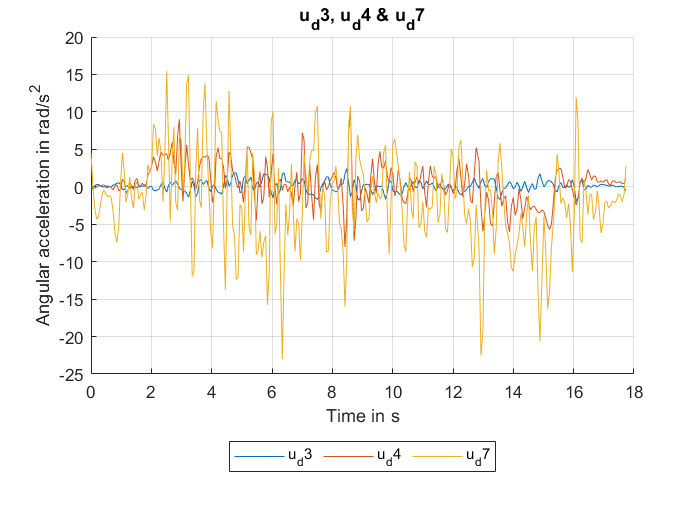


u_d_berekend = [u_dstate_berekend1(:,1) u_dstate_berekend1(:,2) u7_d_dberekend]; %[u_d3 u_d4 u_d7]

u_d347 = figure;
grid on
hold on
plot (time,u_d_berekend(:,1))
plot (time,u_d_berekend(:,2))
plot (time,u_d_berekend(:,3))
title 'u_d3, u_d4 & u_d7'
xlabel 'Time in s'
ylabel 'Angular acceleration in rad/s^2'
legend ('u_d3','u_d4','u_d7','Location','southoutside','Orientation','horizontal')
hold off

**Computing the tire forces**

i = 1;
Ff = zeros(length(yaw_P),1);
Fr = zeros(length(yaw_P),1);

p.d1 = 0.96;
p.d2 = 0.38;
p.d3 = 0.05;
p.g = 9.81;
p.ic11 = 7.178169776497895;
p.ic22 = 11.0;
p.ic31 = 3.8225535938357873;
p.ic33 = 4.821830223502103;
p.id11 = 0.0603;
p.id22 = 0.12;
p.ie11 = 0.05841337700152972;
p.ie22 = 0.06;
p.ie31 = 0.009119225261946298;
p.ie33 = 0.007586622998470264;
p.if11 = 0.1405;
p.if22 = 0.28;
p.l1 = 0.4707271515135145;
p.l2 = -0.47792881146460797;
p.l3 = -0.00597083392418685;
p.l4 = -0.3699518200282974;
p.mc = 85.0;
p.md = 2.0;
p.me = 4.0;
p.mf = 3.0;
p.rf = 0.35;
p.rr = 0.3;

for i = 1:length(yaw_P)-1

    q(i,:) = [q4_berekend(i) q7_berekend(i)];
    u(i,:) = [u_state_berekend(i,2) u6(i) u_state_berekend(i,3)];
    up(i,:) = [u_d4dif(i) u_d6(i) u_d4dif(i)];
    [Ff(i), Fr(i)] = lateral_tire_forces(q(i,:), u(i,:), up(i,:), p);
    
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

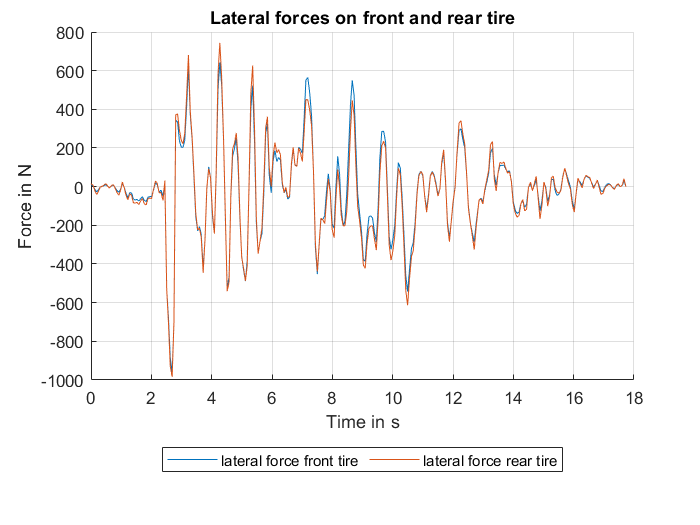

forces = figure;
grid on
hold on
plot (time,Ff)
plot (time,Fr)
title 'Lateral forces on front and rear tire'
xlabel 'Time in s'
ylabel 'Force in N'
legend ('lateral force front tire','lateral force rear tire','Location','southoutside','Orientation','horizontal')
hold off

Safe pictures in current folder

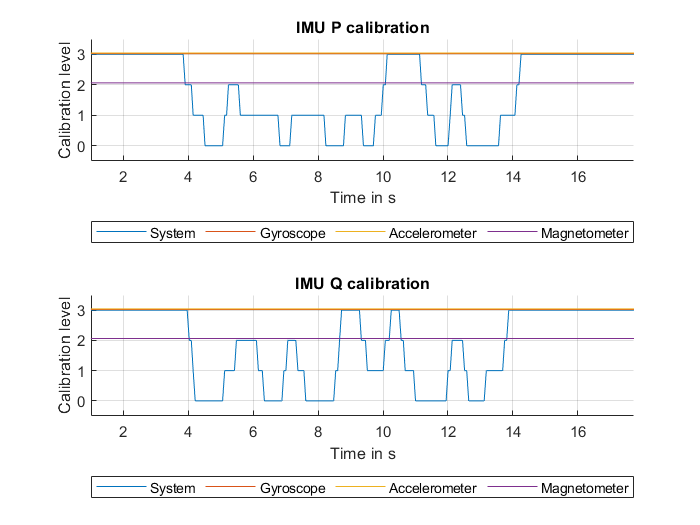

testnaam = "2020-12-16 TEST 3"; %vul hier testnaam in
save(testnaam);
saveas(calibration,""+testnaam+" - Calibration",'png')

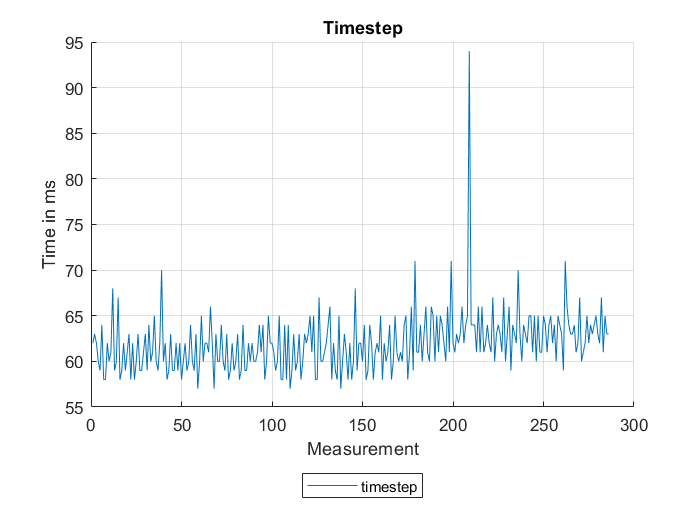

saveas(timestep,""+testnaam+" - timestep",'png')

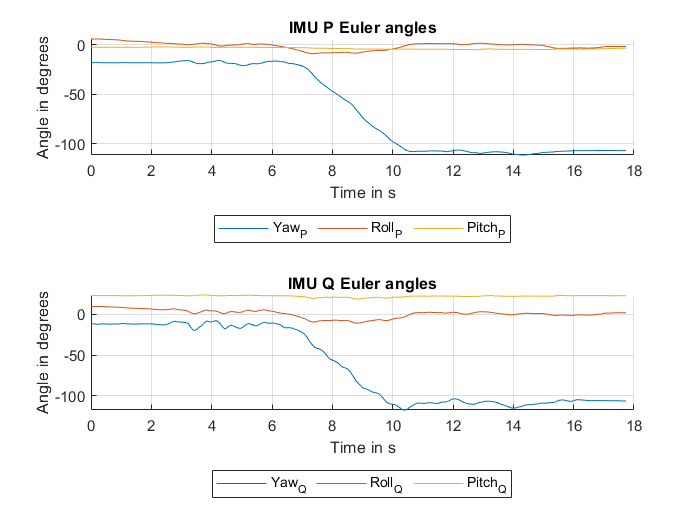

saveas(euler,""+testnaam+" - IMU Euler Angle",'png')

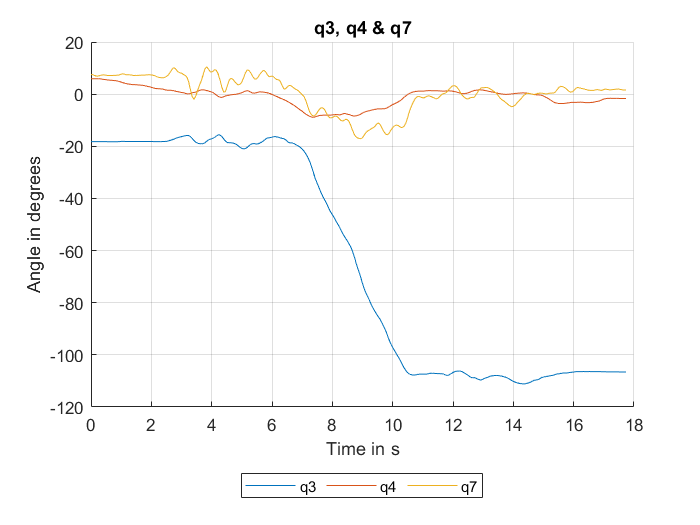

saveas(q347,""+testnaam+" - q3 q4 q7",'png')

saveas(gyro,""+testnaam+" - IMU Gyro",'png')

saveas(u347,""+testnaam+" - u3 u4 u7",'png')

saveas(u_d347,""+testnaam+" - u_d3 u_d4 u_d7",'png')

saveas(u_d347dif,""+testnaam+" - u_d3 u_d4 u_d7 differentiated",'png')

saveas(speed_and_acceleration,""+testnaam+" - speed & acceleration",'png')

saveas(forces,""+testnaam+" - lateral tire forces",'png')

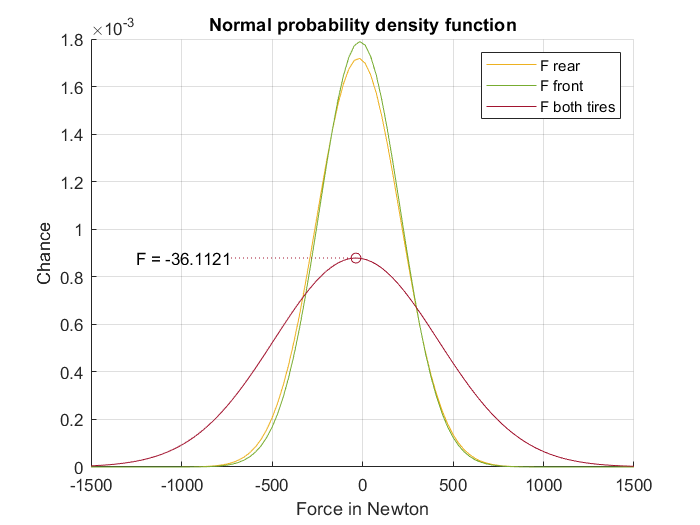

muFr = mean(Fr);
muFf = mean(Ff);
muBoth = mean(Ff+Fr);
sigmaFr = std(Fr);
sigmaFf = std(Ff);
sigmaBoth = std(Ff+Fr);
xs = linspace(-1500,1500,100);
ysFr = normpdf(xs, muFr, sigmaFr);
ysFf = normpdf(xs, muFf, sigmaFf);
ysBoth = normpdf(xs, muBoth, sigmaBoth);
clf;
normdis = figure;
hold on
plot(xs, ysFr, 'color', '#EDB120');
plot(xs, ysFf, 'color', '#77AC30');
plot(xs, ysBoth, 'color', '#A2142F');
plot(muBoth,max(ysBoth), 'marker', 'o', 'color', '#A2142F');
plot([muBoth,-750] , [max(ysBoth),max(ysBoth)], 'LineStyle', ':', 'color', '#A2142F' );
text(-1250,max(ysBoth),append('F = ',num2str(muBoth)));
legend('F rear', 'F front', 'F both tires');
grid on
xlabel('Force in Newton');
ylabel('Chance');
title('Normal probability density function')
saveas(normdis,""+testnaam+" - normal distribution",'png')